# Demo 9: Radiative heat transfer

*Thermal radiation* is the emission of electromagnetic waves as a result of the thermal motion of the particles that constitute matter. All objects at a finite temperature emit thermal radiation, which enables *radiation heat transfer.* This is how the Sun heats the Earth across the vacuum of space, for example.

In this demo, we will review thermal radiation and combine it with what we have learned and coded in previous demos to solve a heat transfer problem. This demo assumes a basic knowledge of thermodynamics and heat transfer.

## Review of thermal radiation

### The blackbody spectrum

Unlike the plane waves we have looked at in previous demos, which are *monochromatic*, thermal radiation is described by a continuous spectrum called **Planck's law**:


$$B\left(\lambda \;,T\right)=\frac{2{\textrm{hc}}^2 }{\lambda^5 }\frac{1}{e^{\textrm{hc}/\left(\lambda k_B T\right)} -1},$$


where $B$ is the power per unit solid angle, per unit area, per unit wavelength (or frequency, or energy, depending on the version of Planck's law). The code below plots $B$ as a function of wavelength at room temperature ($T=300$ K).

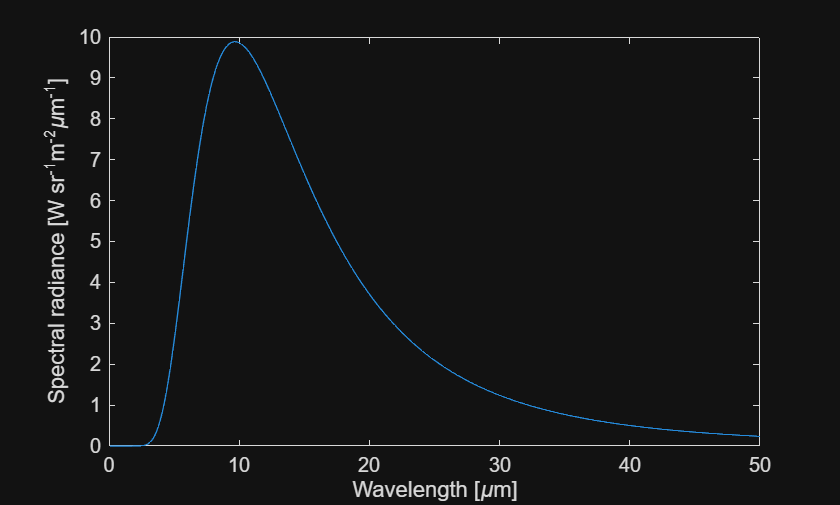

c = 3e8;
h = 6.63e-34;
k_B = 1.38e-23;

lambda = (0.1:0.1:50)*1e-6;
T = 300;

B = (2*h*c^2./(lambda.^5))*1./(exp(h*c./(lambda*k_B*T)) - 1);

figure;
plot(lambda/1e-6, B*1e-6);
xlabel('Wavelength [\mum]');
ylabel('Spectral radiance [W sr^{-1}m^{-2}\mum^{-1}]');

You may have noticed that $B$ peaks at a certain wavelength. It turns out that the peak wavelength of thermal radiation is a function of temperature:


$$\lambda_{\textrm{peak}} =\frac{2898\;\left\lbrack \mu \mathrm{m}\cdot \mathrm{K}\right\rbrack }{T}\ldotp$$


This is known as **Wien's law**. When integrated over all solid angles and wavelengths, Planck's law simplifies to the **Stefan-Boltzmann law**:


$$P=\sigma T^4 ,$$


where $P$ is the power per unit area emitted by the object, $\sigma \approx 5\ldotp 67\times {10}^{-8} \;\mathrm{W}\;{\mathrm{m}}^{-2} \;{\mathrm{K}}^{-4}$ is the Stefan-Boltzmann constant, and $T$ is the *absolute* temperature of the object *in K.*

To be more precise, all of the above describes thermal radiation emitted by *blackbodies*, which are idealized objects that are perfect absorbers and perfect emitters. For this reason, Planck's law is sometimes referred to as the **blackbody spectrum**. By contrast, any object that deviates from Planck's law is considered an imperfect emitter. This leads us to the definition of emissivity.

### Emissivity and absorptivity

There are many different ways to define emissivity, but the definition we are most concerned with is *total hemispherical emissivity:*


$$\epsilon \left(T\right)=\frac{E\left(T\right)}{E_{\textrm{bb}} \left(T\right)}=\frac{\int_{\cap } \int_0^{\infty \;} \left\lbrack \epsilon \left(\lambda ,\theta ,\phi ,T\right)B\left(\lambda ,T\right)\right\rbrack d\lambda \;\cos \theta \;d\Omega }{\sigma T^4 },$$


which is the ratio of the total power per unit area emitted by the object and that emitted by a blackbody at the same temperature. In the above equation, $\theta$ and $\phi$ are the polar and azimuthal angles of emission, $\Omega$ solid angle of emission, and $\epsilon \left(\lambda ,\theta ,\phi \right)$ is the *spectral directional emissivity.* In the outer integral, $\cap$ denotes integration over a hemisphere. The integral over $d\Omega$ can be written in terms of a double integral over $d\theta$ and $d\phi$:


$$\int_{\cap } d\Omega \;=\int_0^{2\pi } \int_0^{\frac{\pi }{2}} \sin \theta \;d\theta \;d\phi \ldotp$$


Given the total hemispherical emissivity, the power per unit area emitted by the object is given by a variation of the Stefan-Boltzmann law:


$$P=\epsilon \left(T\right)\sigma T^4 \ldotp$$


Thus, if we know $\epsilon \left(\lambda ,\theta ,\phi ,T\right),$ it should be relatively straightforward to determine $\epsilon \left(T\right)\ldotp$ It turns out that spectral directional emissivity and spectral directional absorptivity are connected via **Kirchhoff's law of radiation**:


$$\epsilon \left(\omega ,\theta ,\phi ,T\right)=\alpha \left(\omega ,\theta ,\phi ,T\right)\ldotp$$


In other words, at a given frequency and in a given direction, emissivity and absorptivity are equal. In fact, this is true of the total hemispherical variations of these quantities:


$$\epsilon \left(T\right)=\alpha \left(T\right)\ldotp$$


Actually, we know how to calculate $\alpha \left(\omega ,\theta ,\phi ,T\right)\ldotp$ In Demo 1, we established that the following equality holds for a planar, semi-infinite (or sufficiently thick) slab in air:


$$R\left(\lambda ,\theta ,\phi ,T\right)+T\left(\lambda ,\theta ,\phi ,T\right)=1,$$


where $R$ is the reflectivity and $T$ is the transmissivity. This is a result of conservation of energy. Moreover, if we are talking about a semi-infinite slab, everything that is transmitted must eventually be absorbed. Therefore,


$$\alpha \left(\lambda ,\theta ,\phi ,T\right)=T\left(\lambda ,\theta ,\phi ,T\right)=1-R\left(\lambda ,\theta ,\phi ,T\right)\ldotp$$


As a result of Kirchhoff's law of radiation,


$$\epsilon \left(\lambda ,\theta ,\phi ,T\right)=1-R\left(\lambda ,\theta ,\phi ,T\right)\ldotp$$


Hence, if we know the reflectivity (or reflectance) of the surface as a function $\lambda ,$ $\theta ,$ and $\phi ,$ we know $\epsilon \left(\lambda ,\theta ,\phi ,T\right)\ldotp$ Note that we are assuming the object is planar and either semi-infinite or sufficiently thick that it can be considered as such. For arbitrarily-shaped objects that simultaneously reflect, transmit, and absorb, the situation becomes more complicated.

## Part 1

### (a) Emissivity of a blackbody

What is the spectral directional emissivity of a blackbody? Total hemispherical emissivity?

*Spectral directional emissivitiy ofa blackbody is 1 for all wavelengths and all directions. Since a blackbody is the max possible emission, the ratio of radiation emitted by a real surface to intensity of a blackbody emission must be 1. The hemispherical emissivity is also 1, because the average of the spectral directional emissivity over the entire hemisphercal solid angle and the electromagnetic spectrum. It must also be 1.*

### (b) Calculating emissivity by hand

It may not look like much, but $\epsilon \left(T\right)$ is very difficult to evaluate in general. Nowadays, we have powerful numerical integration techniques that can be used to evaluate $\epsilon \left(T\right),$ but in the olden days, scientists and engineers used the so-called *fractional function:*


$$f\left(\lambda ,T\right)=\frac{\int_0^{\lambda } B\left(\lambda^{\prime } ,T\right)d\lambda^{\prime } }{\sigma T^4 }\ldotp$$


Many sources will express $f\left(\lambda ,T\right)$ in terms of $\lambda T$ by performing the change of variables $\zeta =C_2 /\lambda T$:


$$f\left(\lambda T\right)=\frac{C_1 }{\sigma C_2^4 }\int_{\zeta }^{\infty } \frac{\zeta^3 }{e^{\zeta } -1}d\zeta \ldotp$$


If $\epsilon \left(\lambda ,\theta ,\phi ,T\right)$ can be approximated as a piecewise constant function, the integration over $\lambda$ can be written in the form


$$\begin{array}{l}
\frac{\int_0^{\infty \;} \epsilon \left(\lambda ,\theta ,\phi ,T\right)B\left(\lambda ,T\right)d\lambda }{\sigma T^4 }\approx \frac{\int_0^{\lambda_1 } \epsilon_1 \left(\theta ,\phi ,T\right)B\left(\lambda ,T\right)d\lambda }{\sigma T^4 }+\frac{\int_{\lambda_1 }^{\lambda_2 } \epsilon_2 \left(\theta ,\phi ,T\right)B\left(\lambda ,T\right)d\lambda }{\sigma T^4 }+\frac{\int_{\lambda_2 }^{\lambda_3 } \epsilon_3 \left(\theta ,\phi ,T\right)B\left(\lambda ,T\right)d\lambda }{\sigma T^4 }+\ldotp \ldotp \ldotp \\
=\sum_{n=1}^{\infty } \frac{\int_{\lambda_{n-1} }^{\lambda_n } \epsilon_n \left(\theta ,\phi ,T\right)B\left(\lambda ,T\right)d\lambda }{\sigma T^4 },
\end{array}$$


where $\lambda_0 =0\ldotp$ But since each $\epsilon_n \left(\theta ,\phi ,T\right)$ is constant with respect to $\lambda ,$ they can be pulled out of the integrals, and what remains can be written in terms of fractional functions:


$$\begin{array}{l}
\sum_{n=1}^{\infty } \frac{\int_{\lambda_{n-1} }^{\lambda_n } \epsilon_n \left(\theta ,\phi ,T\right)B\left(\lambda ,T\right)d\lambda }{\sigma T^4 }=\sum_{n=1}^{\infty } \epsilon_n \left(\theta ,\phi ,T\right)\frac{\int_{\lambda_{n-1} }^{\lambda_n } B\left(\lambda ,T\right)d\lambda }{\sigma T^4 }=\sum_{n=1}^{\infty } \epsilon_n \left(\theta ,\phi ,T\right)\left\lbrack \frac{\int_0^{\lambda_n } B\left(\lambda ,T\right)d\lambda -\int_0^{\lambda_{n-1} } B\left(\lambda ,T\right)d\lambda }{\sigma T^4 }\right\rbrack \\
=\sum_{n=1}^{\infty } \epsilon_n \left(\theta ,\phi ,T\right)\left\lbrack f\left(\lambda_n T\right)-f\left(\lambda_{n-1} T\right)\right\rbrack \ldotp 
\end{array}$$


**Now consider a surface whose spectral directional emissivity is described by the following piecewise constant function:**


$$\epsilon \left(\lambda ,\theta ,\phi ,T\right)=\epsilon \left(\lambda \right)=\left\lbrace \begin{array}{ll}
0\ldotp 8 & 0\le \lambda <1\;\mu \mathrm{m}\\
0\ldotp 2 & 1\le \lambda <3\;\mu \mathrm{m}\\
0 & \lambda \ge 3\;\mu \mathrm{m}
\end{array}\right.$$


Use the tabulated values of $f\left(\lambda_n T\right)$ in `MillsFractionalFunction.pdf` `to` calculate the total hemispherical emissivity by hand. If the surface temperature is 1000 K, what is the power per unit area emitted by the object? How would you engineer $\epsilon \left(\lambda \right)$ to maximize this value? (Hint: think about Wien's law!)

- *Define the wavelength intervals for the glass.*

- *Calculate the parameter *$$v_i = \lambda_i T$$* for each boundary.*

- *Locate *$$F(0 \to v_i)$ $*in the Mills table.*

- *Compute the fraction of energy in each band: *$$\Delta F_i = F_{i+1} - F_i$.$

- *Sum the products: *$$\epsilon = \epsilon_1 \Delta F_1 + \epsilon_2 \Delta F_2 + \dots$$


$$$$\epsilon(T) = \sum_{i=1}^{n} \epsilon_{\lambda, i} \left[ F(0 \to \lambda_{i+1}T) - F(0 \to \lambda_i T) \right]$$
$$E = \epsilon \sigma T^4$$
$\sigma = 5.67 \times 10^{-8} \text{ W/m}^2\cdot\text{K}^4$            
$$



$$ $T = 1000 \text{ K}$
$$E = \epsilon \cdot (5.67 \times 10^{-8} \text{ W/m}^2\cdot\text{K}^4) \cdot (1000 \text{ K})^4$$$$E = \epsilon \cdot 56,700 \text{ W/m}^2$$
$$\lambda_{max} = \frac{C_3}{T}$$
$$\lambda_{max} = \frac{2898 \text{ microns}\cdot\text{K}}{1000 \text{ K}} = 2.898 \text{ microns}$$$$


### (c) Calculating emissivity numerically

Consider a surface whose refractive index is 1.91 (the reported value for hafnium oxide). Calculate the reflectivity of the surface as a function of $\lambda$ and $\theta$ using `reflCoeff.m`, which you coded in Demo 1.

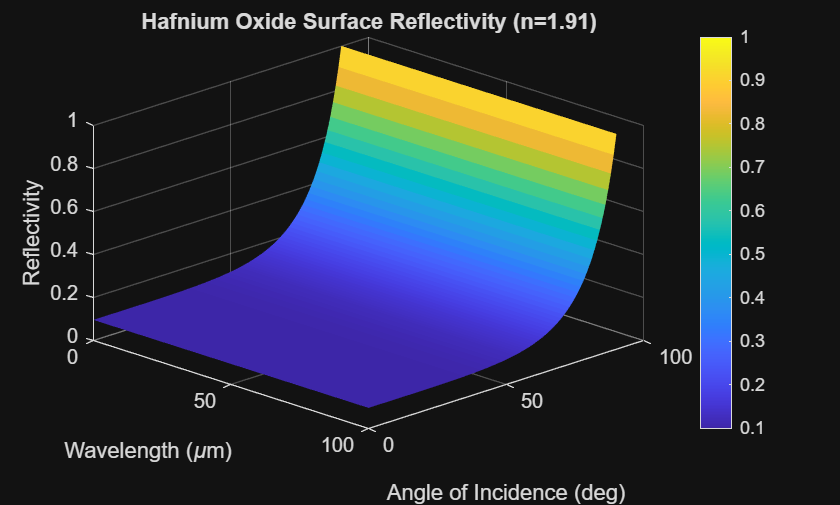

theta = (0:1:90)*pi/180; % Polar angle of incidence [rad].
lambda = (0.1:0.1:100)*1e-6; % Wavelength [m].
n = 1.91; % Refractive index [1].
epsilon = n^2; % Dielectric constant.
c = 3e8; % Speed of light [m/s].

% Preallocate array.
R = zeros(length(theta), length(lambda));

% === TYPE YOUR CODE BELOW === %

for i = 1:length(theta)
    for j = 1:length(lambda)
        omega = 2 * pi *c / lambda(j); %angular frequency at this wavelength
        [rp, rs] = reflCoeff(omega, epsilon, theta(i)*180/pi);

        %calculate reflectivity R = (rs^2 + rp^2) /2
        R(i,j) = (abs(rs)^2 + abs(rp)^2)/2;
    end

end

% Plotting the results
figure;
[LAM, TH] = meshgrid(lambda*1e6, theta*180/pi);
surf(LAM, TH, R, 'EdgeColor', 'none');
xlabel('Wavelength (\mum)');
ylabel('Angle of Incidence (deg)');
zlabel('Reflectivity');
title('Hafnium Oxide Surface Reflectivity (n=1.91)');
view(45, 30);
colorbar;

Using this information, calculate the total hemispherical emissivity of the surface. You can use the built-in function `trapz` to evaluate the integral. (Hint: The reflectivity is *not* a function of $\phi \ldotp$ This means the integral over $d\phi$ simplifies to $2\pi \ldotp$ If you are code-savvy, you can do it in one line by nesting `trapz` functions!)

B = (2*h*c^2./(lambda.^5))*1./(exp(h*c./(lambda*k_B*T)) - 1); % Blackbody spectral radiance [W/sr/m^3].

sigma = 5.67e-8; % Stefan-Boltzmann constant [W/m^2/K^4].
T = 300; % Temperature [K].

epsilon_lambda_theta = 1-R; %Kirchoff's Law: emissivity =  1- reflectivity
weight = sin(theta') .* cos(theta'); %hemispherical integration weight

%Inner trapz integrates over theta; outer trapz integrates over lambda.
numerator = trapz(lambda, trapz(theta, epsilon_lambda_theta .*weight, 1) * 2* pi .* B);
denominator = sigma * T^4;

epsilon_total = numerator / denominator;

### (d) Spectral emissivity of silicon carbide

Silicon carbide is a *polar dielectric* whose dielectric function is given by


$$\varepsilon \left(\omega \right)=\varepsilon_{\infty \;} \frac{\omega^2 -\omega_{\textrm{LO}}^2 +i\gamma \omega }{\omega^2 -\omega_{\textrm{TO}}^2 +i\gamma \omega },$$


where $\omega_{\textrm{LO}} =0\ldotp 12$ eV is the longitudinal optical phonon frequency, $\omega_{\textrm{TO}} =0\ldotp 098$ eV is the transverse optical phonon frequency, $\gamma =0\ldotp 588$ meV is the damping constant, and $\varepsilon_{\infty \;} =6\ldotp 7$. (Note that 1 eV = $e/\hbar$ rad/s.)

Calculate the *spectral hemispherical emissivity* and the total hemispherical emissivity of a silicon carbide surface. Plot the spectral hemispherical emissivity. What do you notice about the peaks in the spectrum?

Hint: The spectral hemispherical emissivity is just the spectral directional emissivity integrated over a hemisphere:


$$\epsilon \left(\lambda ,T\right)=\frac{1}{\pi }\int_0^{2\pi } \int_0^{\frac{\pi }{2}} \epsilon \left(\lambda ,\theta ,\phi ,T\right)\cos \theta \;\sin \theta \;d\theta \;d\phi \ldotp$$


hbar = 1.055e-34;
e = 1.602e-19;
k_B = 1.38e-23;
c=3e8;
ev_to_rad = 1.519e15;

w_LO = 0.120 * ev_to_rad;
w_TO = 0.098 * ev_to_rad;
gamma = 0.0005 * ev_to_rad;
eps_inf = 6.7;

theta = (0:1:90)*pi/180;
lambda = (0.1:0.1:100)*1e-6;
omega = 2*pi*c./lambda; % Angular frequency [rad/s].

% Dielectric function of silicon carbide.
% 1. Calculate Dielectric Function epsilon(omega)
eps_sic = eps_inf * (w_LO^2 - omega.^2 - 1i*gamma*omega) ./ (w_TO^2 - omega.^2 - 1i*gamma*omega);

% 2. Calculate Reflectivity R(theta, lambda)
%Preallocate array
R = zeros(length(theta), length(lambda));
for i = 1:length(theta)
    th_i = theta(i);
    % r_s and r_p coefficients 
    kz1 = (omega/c) * cos(th_i);
    kzt = (omega/c) .* sqrt(eps_sic - sin(th_i)^2);
    
    rs = (kz1 - kzt) ./ (kz1 + kzt);
    rp = (eps_sic.*kz1 - kzt) ./ (eps_sic.*kz1 + kzt);
    R(i, :) = (abs(rs).^2 + abs(rp).^2) / 2;
end

% 3. Spectral Hemispherical Emissivity
% epsilon(lambda) = 2 * integral[ (1-R)*sin(theta)*cos(theta) d_theta ]
eps_spectral_dir = 1 - R;
eps_spectral_hemi = 2 * trapz(theta, eps_spectral_dir .* sin(theta)' .* cos(theta)', 1);


% 4. Total Hemispherical Emissivity
B = (2*h*c^2./(lambda.^5))*1./(exp(h*c./(lambda*k_B*T)) - 1); % Blackbody spectral radiance [W/sr/m^3].
sigma = 5.67e-8; % Stefan-Boltzmann constant [W/m^2/K^4].
T = 300; % Temperature [K].

total_emissivity = trapz(lambda, eps_spectral_hemi .* B * pi) / (sigma * T^4)

total_emissivity = 0.6011

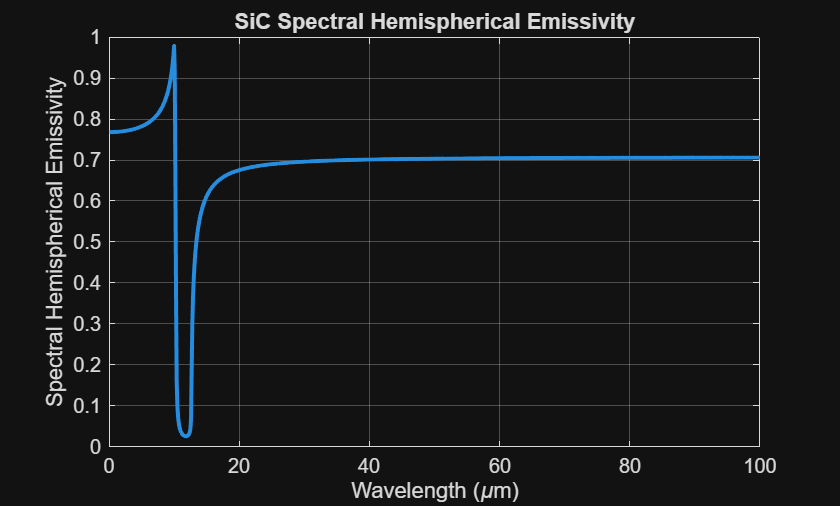


% Plotting
figure;
plot(lambda*1e6, eps_spectral_hemi, 'LineWidth', 2);
xlabel('Wavelength (\mum)'); ylabel('Spectral Hemispherical Emissivity');
title('SiC Spectral Hemispherical Emissivity'); grid on;

%The peaks in the spectrum correspond to the wavelengths where it acts like
%a metal (eps<0, R~1), and where it is in the Reststrahlen Band.
%High-reflectivity is the basis for surface phonon-polariton mode
%excitation, where there is strong momentum mistmatch and light can be
%confined at the ssurface.

## Part 2

Consider a piece of glass sitting outside on a hot day. The glass is emitting thermal radiation while being irradiated by the sun, which heats it up. It also loses heat because of natural convection. The refractive index of glass is tabulated in `siO2_popova_1972.csv`. The solar irradiance at sea level is approximately $1000\;\mathrm{W}\;{\mathrm{m}}^{-2}$. The heat transfer coefficient of natural convection at an air temperature of 30 °C is $10\;\mathrm{W}\;{\mathrm{m}}^{-2} \;{\mathrm{K}}^{-1} \ldotp$ Our goal is to determine the surface temperature of the glass.

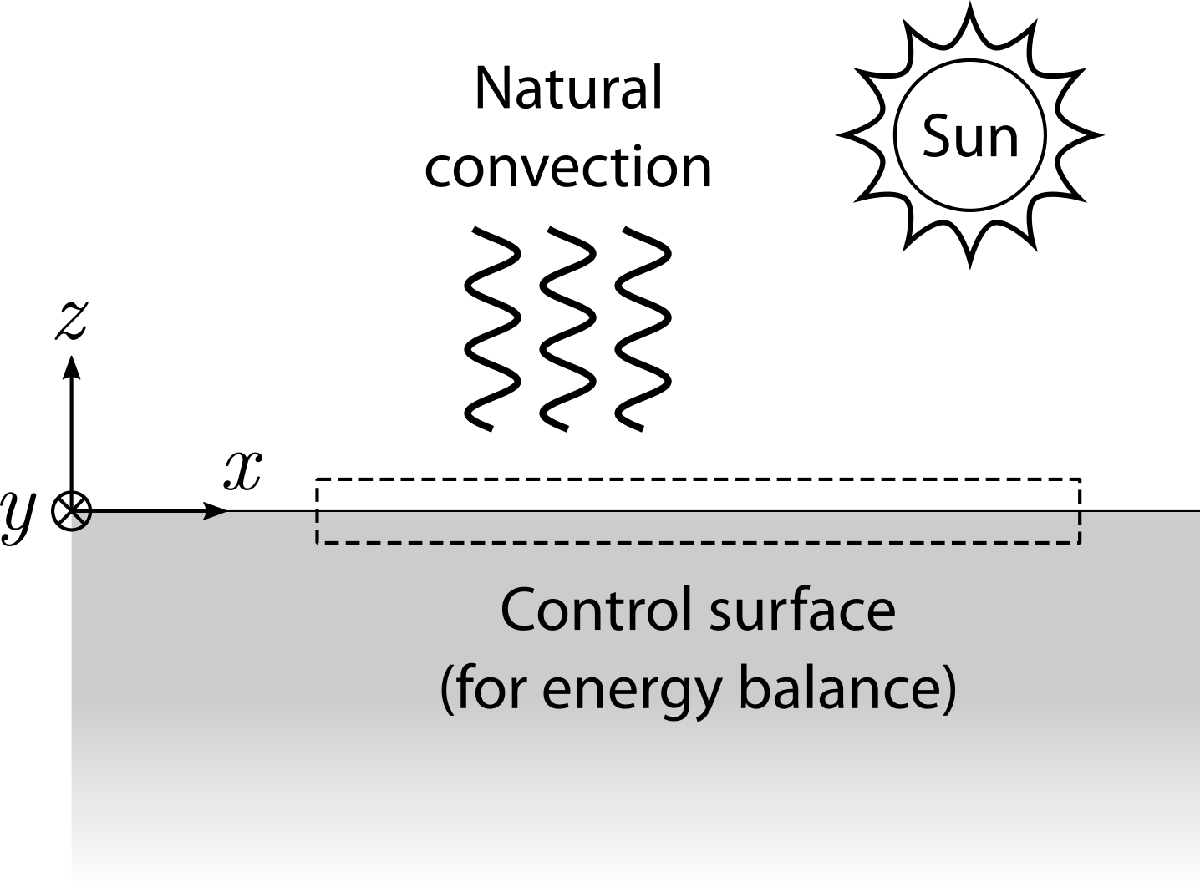

### (a) Energy balance

The first law of thermodynamics, in rate form, states that


$$\frac{\partial E}{\partial t}=\dot{Q} -\dot{W} ,$$


where $E$ is the total internal energy, $\dot{Q}$ is the rate of heat transfer, and $\dot{W}$ is the rate of work. If no work is being done and the system is at steady state, this simplifies to


$$\dot{Q} =0\ldotp$$


In other words, all the heat transfer into and out of the system has to balance out.

Derive the governing equation for the temperature of the glass $T$ in terms of the heat transfer coefficient $h,$ area of the glass $A,$ air temperature $T_{\textrm{air}} ,$ total hemispherical emissivity of the glass $\epsilon \left(T\right),$ and rate of solar energy absorption ${\dot{Q} }_{\textrm{solar}}$.

$\dot{Q_{\mathrm{solar}} } =\mathrm{hA}\left(T-T_{\mathrm{infinity}} \right)+\epsilon A\sigma \left(T^4 -{T_{\mathrm{infinity}} }^4 \right)$***. Given the presence of T in both the radiation and convection term, solving for T explicitly requires numerical methods.***

### (b) Total hemispherical emissivity

Calculate the total hemispherical emissivity of the glass.

% Constants
c = 2.9979e8;         % Speed of light [m/s]
h = 6.626e-34;        % Planck's constant [J*s]
kB = 1.3806e-23;      % Boltzmann constant [J/K]
sigma = 5.67037e-8;   % Stefan-Boltzmann constant [W/(m^2*K^4)]

% Temperature of the glass
T = 300; % [K] - Adjust as needed

% Import the frequencies and dielectric function (from Popova 1972)
data = readmatrix('siO2_popova_1972.csv', 'NumHeaderLines', 1);
lambda = data(:,1).' * 1e-6; % Convert microns to meters
n = data(:,2).';
k = data(:,3).';
epsilon_complex = (n + 1i*k).^2;

% Angle array
theta = (0:1:90) * pi/180;

% Preallocate arrays
R_unpol = zeros(length(theta), length(lambda));

% 1. Calculate Spectral-Directional Reflectivity R(theta, lambda)
for j = 1:length(lambda)
    % Fresnel equations for each angle at this wavelength
    sin_theta = sin(theta);
    % Using Snell's Law for complex refractive index
    % costhetat = sqrt(1 - (sin(theta)/complex_n)^2)
    cos_theta_i = cos(theta);
    
    % Complex refractive index at this wavelength
    m = n(j) + 1i*k(j);
    
    % Intermediate term for Fresnel calculation
    % sqrt(m^2 - sin^2(theta))
    xi = sqrt(m^2 - sin_theta.^2);
    
    % Fresnel Reflection Coefficients (r_perpendicular and r_parallel)
    rs = (cos_theta_i - xi) ./ (cos_theta_i + xi);
    rp = (m^2 * cos_theta_i - xi) ./ (m^2 * cos_theta_i + xi);
    
    % Reflectivity for unpolarized light
    R_unpol(:,j) = (abs(rs).^2 + abs(rp).^2) / 2;
end

% 2. Calculate Hemispherical Spectral Emissivity epsilon(lambda)
% Integrate R over angle: R_hem(lambda) = 2 * integral(R * sin(theta) * cos(theta) d_theta)
% Then epsilon(lambda) = 1 - R_hem(lambda)
R_hem_lambda = zeros(1, length(lambda));
for j = 1:length(lambda)
    R_hem_lambda(j) = trapz(theta, R_unpol(:,j).' .* sin(theta) .* cos(theta)) * 2;
end
eps_lambda = 1 - R_hem_lambda;

% 3. Calculate Total Hemispherical Emissivity (weighted by Planck's Law)
% Planck's Law: Eb_lambda [W/m^3]
C1 = 2 * pi * h * c^2;
C2 = h * c / kB;
Eb_lambda = (C1 ./ lambda.^5) ./ (exp(C2 ./ (lambda .* T)) - 1);

% Integrate over wavelength
numerator = trapz(lambda, eps_lambda .* Eb_lambda);
denominator = sigma * T^4;

epsilon_total = numerator / denominator;

fprintf('The total hemispherical emissivity is: %0.4f\n', epsilon_total);

The total hemispherical emissivity is: 0.6850


### (c) Solving the governing equation using fixed point iteration

We will attempt to solve the governing equation using a method called *fixed point iteration. *Given an initial guess $T_0 ,$ the governing equation can be solved by rewriting it in the form $f\left(T\right)=T$ and performing the iteration


$$f\left(T_n \right)=T_{n+1} ,$$
 
$$n=0,1,2,\ldotp \ldotp \ldotp$$


in the hopes that $T_n$ approaches the "true value." The equation can be considered solved when the percent error falls below tolerance. The percent error is defined as


$$%\Delta_n =100%\times \frac{x_n -x_{n-1} }{x_{n-1} }\ldotp$$


Open the file` fixedPointIteration.m` and complete the code that solves equations of the form $f\left(x\right)=x\ldotp$ Then, call `fixedPointIteration` to solve the governing equation. What is the temperature of the glass?

h = 10; % Heat transfer coefficient [W/m^2/K].
A = 1; % Area of the glass [m^2].
T_air = 303; % Air temperature [K].

sigma = 5.67e-8;
T_sun = 5800; % Sun temperature [K].
%absorptivity = emissivity; % From Kirchhoff's law of radiation.
Q_solar = epsilon_total*A*1000; % Rate of solar energy absorption [W].

% === TYPE YOUR CODE BELOW === %
% Governing equation in the form f(x) = x:

% Define the symbolic variable for Temperature
syms T_sym

% Rearrange the equation into the form T = f(T)
% f(T) = (Q_solar + h*A*T_air - epsilon_total*A*sigma*(T^4 - T_air^4)) / (h*A)
f_sym = (Q_solar + h*A*T_air - epsilon_total*A*sigma*(T_sym^4 - T_air^4)) / (h*A);

% Parameters for iteration
x_0 = 310;       % Initial guess slightly above air temp
tolerance = 0.01; % 0.01% error
n = 100;         % Max iterations

% Call the fixed-point iteration function
[T_solution, error_history] = fixedPointIteration(f_sym, x_0, tolerance, n);

% Display results
fprintf('The steady-state temperature of the glass is: %0.2f K\n', T_solution);

The steady-state temperature of the glass is: 347.57 K


Plot the percent error as a function of the iteration number. How many iterations did it take to solve the governing equation?

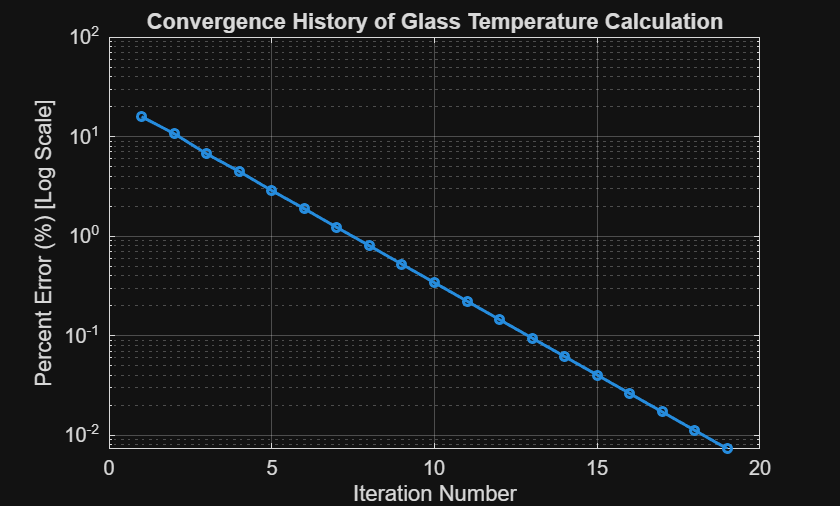

% === Plotting the Convergence === %

% Create a new figure for the error plot
figure;
% Plot iteration number vs. percent error
% 1:length(error_history) creates the x-axis for each iteration step
plot(1:length(error_history), error_history, '-o', 'LineWidth', 1.5, 'MarkerSize', 4);

% Label the axes and add a title
xlabel('Iteration Number');
ylabel('Percent Error (%)');
title('Convergence History of Glass Temperature Calculation');

% Improve plot readability
grid on;
set(gca, 'YScale', 'log'); % Use a log scale if error drops rapidly
ylabel('Percent Error (%) [Log Scale]');

% === Determining the Iteration Count === %
% The number of iterations is simply the number of elements in the error array
num_iterations = length(error_history);

% Display the final results to the command window
fprintf('Final Temperature: %0.4f K\n', T_solution);

Final Temperature: 347.5726 K


fprintf('Total Iterations required: %d\n', num_iterations);

Total Iterations required: 19


### (d) Solving the governing equation using Newton's method

We can also solve the governing equation using *Newton's method.* It is a root-finding algorithm, which means we need to rewrite the governing equation in the form $g\left(T\right)=0\ldotp$ Given an initial guess $T_0$, we can find the roots of $g\left(T\right)$ by performing the iteration


$$T_{n+1} =T_n -\frac{g\left(T_n \right)}{g^{\prime } \left(T_n \right)},$$


where $g^{\prime } \left(T\right)$ is the first derivative of $g\left(T\right)\ldotp$

Open the file` NewtonsMethod.m` and complete the code that finds the roots of an arbitrary function $g\left(x\right)\ldotp$ Then, call `NewtonsMethod` to solve the governing equation. What is the temperature of the glass this time? Given the same initial guess and tolerance, how many iterations did it take compared to fixed point iteration?

Hint: Your code for `NewtonsMethod.m` should be very similar to `FixedPointIteration.m`. You only need to change one or two lines of code.

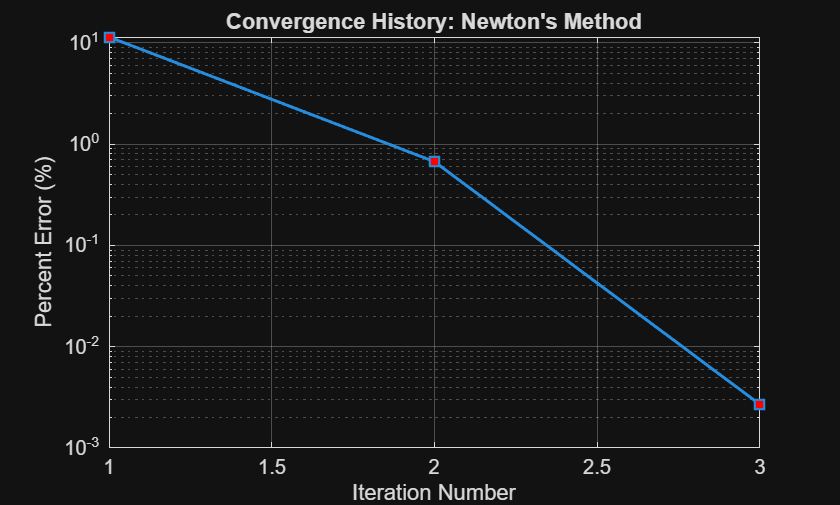

h = 10;
A = 1;
T_air = 303;

sigma = 5.67e-8;
T_sun = 5800;
Q_solar = epsilon_total*A*1000;
% === TYPE YOUR CODE BELOW === %
% Governing equation in the form g(x) = 0:
% Define the symbolic variable for Temperature
syms T_sym

% Governing equation in the form g(T) = 0
g_sym = Q_solar - h*A*(T_sym - T_air) - epsilon_total*A*sigma*(T_sym^4 - T_air^4);

% Parameters for iteration
x_0 = 310;        % Initial guess [K]
tolerance = 0.01;  % 0.01% error
n = 100;          % Max iterations

% Call the Newton's Method function
[T_solution_newton, error_newton] = NewtonsMethod(g_sym, x_0, tolerance, n);

% Plot the convergence for Newton's Method
figure;
plot(1:length(error_newton), error_newton, '-s', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
set(gca, 'YScale', 'log');
grid on;
xlabel('Iteration Number');
ylabel('Percent Error (%)');
title('Convergence History: Newton''s Method');

% Display results
fprintf('Final Temperature: %0.4f K\n', T_solution_newton);

Final Temperature: 347.5626 K


fprintf('Total Iterations: %d\n', length(error_newton));

Total Iterations: 3
